clc
clear

mu = 5.35;
sigma = 0.4;

x = 0:720;
y = lognpdf(x,mu,sigma);

pd = makedist('Lognormal','mu',mu,'sigma',sigma);
m = mean(pd)

m = 228.1492

s = std(pd)

s = 95.0347

mode = exp(mu-sigma^2)

mode = 179.4686

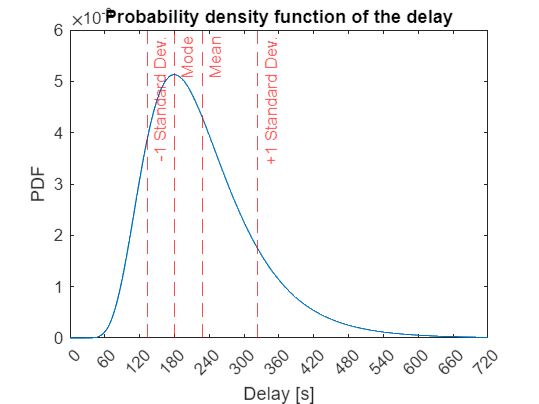


figure()
plot(x,y)
grid off
title("Probability density function of the delay") % using linearisation at each step
ylabel("PDF")
xlabel("Delay [s]")
xlim([0,720])
xticks(0:60:720)
xline([m-s m m+s mode],'--r',{'-1 Standard Dev.','Mean','+1 Standard Dev.','Mode'})
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/PDFPlot','epsc')